function createGeomSolidCircPattern(PartName,SolidId,MachineData,geomApp)

% 
% PartName=AssemTable.AssemItemName{2}
% PartObj =AssemTable.AssemItem(2)


geomDocu=geomApp.GetDocument;
% aRefObj=geomDocu.CreateReferenceFromItem(PartObj);
% BodyName=aRefObj.GetIdentifier;

{'Conductor_' } {'RotorAir' } {'Insulation' } {'StatorCore' } {'otherSlotArea'} {'RotorCore' } {'RotorMagnet' }

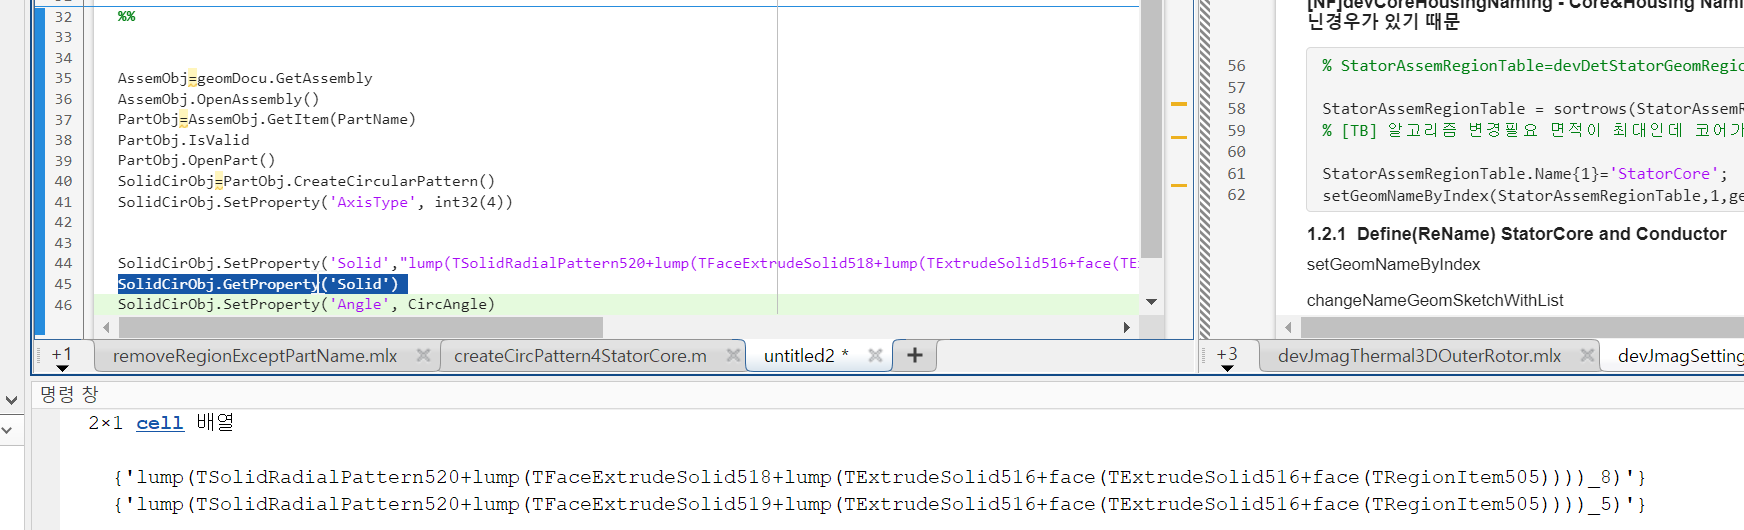

if contains(PartName,'Stator','IgnoreCase',true)||contains(PartName,'Coil','IgnoreCase',true)||contains(PartName,'Slot','IgnoreCase',true) ||contains(PartName,'Insulation','IgnoreCase',true)||contains(PartName,'Conductor','IgnoreCase',true)
    CircAngle = MachineData.StatorOneSlotAngle;
    NumberInstance= MachineData.slots;

elseif contains(PartName,'Magnet','IgnoreCase',true)|| contains(PartName,'Rotor','IgnoreCase',true)
    CircAngle = 360/MachineData.Poles;
    NumberInstance= MachineData.Poles;
   
end
    AssemObj=geomDocu.GetAssembly;
    AssemObj.OpenAssembly()
    PartObj=AssemObj.GetItem(PartName);
    PartObj.IsValid
    PartObj.OpenPart()
    SolidCirObj=PartObj.CreateCircularPattern();
    SolidCirObj.SetProperty('AxisType', int32(4))

    for i=1:length(SolidId)
    RefObj=geomDocu.CreateReferenceFromIdentifier(SolidId{i});
    SolidCirObj.AddPropertyByReference('Solid',RefObj)
    end
SolidcellList=SolidCirObj.GetProperty('Solid')
SolidCirObj.SetProperty('Angle', CircAngle)
SolidCirObj.SetProperty('Instance', int32(NumberInstance))
end